# Visualisation des donnees Mars sur cartes

## Avant de lancer le script

Ligne 3 à 5 : Choisir le chemin d'accès selon l'ordinateur

Ligne 8 : Choisir le programme sur lequel faire la sortie graphique

Ligne 25 à 29 : Choix de la gamme des boucles des sorties, dont edit pour choisir 1: planche par predict et saison toutes les années, 2 : planche par predict et année toutes saisons, 3 : carte individuelle

clear; clc;
ticvariable

## Definition des variables contextuelles

pc = 'E:/'; % 'C:/Users/lehuen201/Nextcloud/'; % 'Z:/'; %
tsk = 'A_SDM_NEO/';
site = 'ES'; % 'BDV' 'BDS' 'ES'

wdpath = [pc 'Melting Pot/BDD/']; 
wdwork = [wdpath,tsk,'Matrices/'];
wdgraph = [wdpath,tsk,'Graphiques/','Maps/',site,'/'];

etude = [site,'_Mars'];
an = [1990:1991 1993:2000 2005:2018]; % 1992 toute plantée enlevée
nc2d = load ([wdwork, etude, '_Nc2D']);
palette = 'jet';

% cou = 1:length(nc2d.couche); % choix hyd sed ou MEVE
sai = 1:size(nc2d.saison,1); saison=nc2d.saison; % year, summer, winter
per = 1:length(an);
edit = 3; % Choix 1: planche tous les ans par saison, 2:planche une année 3 saisons (long), 3:individuel (very long!), ou combinaisons
editgif = 1; % GIF edition ? WARNING : very time consuming
csp = 4; lsp = ceil(size(an,2)/csp);
propplch = [0 0 600 500];  
propimg = [0 0 600 500];
finesse = 100;

# Données Hydrologiques puis Sedimentaires

% for co = cou
% if co==3; sai=1; end % for tides data non season to speed up
% predict = eval(['nc2d.couche{' num2str(co) ',1} ;']);
predict = nc2d.predict;
pred = 1:size(predict,1);
make_it_tight = true;
subplot = @(m,n,p) subtightplot (m, n, p, [0.07 0.05], [0.05 0.11], [0.05 0.12]); %[0.01 0.05], [0.1 0.01], [0.1 0.01]
if ~make_it_tight,  clear subplot;  end

## Planche saison avec tous les ans

if edit == 1 || edit == 12 || edit == 13 || edit == 123
    for pre = pred
        for sa = sai
        figure;clf;hold on
        
        % Recherche gamme maximale sur la periode pour echelle commune
        varmax = strcat("max(",predict{pre,1},saison{sa,1},'_',string(an),",[],'all')"); maxx = 0;
        varmin = strcat("min(",predict{pre,1},saison{sa,1},'_',string(an),",[],'all')"); minn = 0;
        for i = 1:length(varmax)
          try maxx = max(maxx,eval(varmax(i))); end
          try minn = min(minn,eval(varmin(i))); end
        end
        rgvar = [minn maxx];
        
        set(gcf, 'Position', propplch);
          for ann = per
            anstr = num2str(an(ann));
            subplot(lsp,csp,ann);hold on
              x = eval(['nc2d.lon_nc_' anstr ';']);
              y = eval(['nc2d.lat_nc_' anstr ';']);
              z = eval(['nc2d.' predict{pre,1} saison{sa,1} '_' anstr ';']); 
              contourf(x,y,z,finesse, 'LineColor','flat')
              caxis(rgvar);colormap(palette);
              title(anstr);
          end
          hpf = get(subplot(lsp,csp,lsp*csp),'Position');
          caxis(rgvar);
          c = colorbar('Position', [hpf(1)+hpf(3)+0.1 hpf(2) 0.01 hpf(2)*lsp+hpf(4)*lsp], 'AxisLocation', 'in');
          c.Label.String = sprintf('%s (%s)', strrep(predict{pre,2},'_',' '), predict{pre,3}); c.Label.FontSize = 12; c.FontSize = 12;
          titreG = sprintf('%s (%s) : %s in %s', strrep(predict{pre,1},'_',' '), predict{pre,3}, predict{pre,2}, saison{sa,2});
          [~,h3] = suplabel(titreG ,'t'); set(h3,'FontSize',12,'Position',[.5 1.03 0.5]);
          hold off
        saveas(gcf,[wdgraph,etude,'_Maps_',predict{pre,1},'_',saison{sa,2},'.png']);
        end
    end
end

## Planche annuelle avec les 3 saisons

if (edit == 2 || edit == 12 || edit == 23 || edit == 123) % co~=3 && 
    lspy=1; cspy=3;
    for pre = pred
        for ann = per
        anstr = num2str(an(ann));
        figure;clf;hold on
        % Recherche gamme maximale sur la periode pour echelle commune
        varmax = strcat("max(nc2d.",predict{pre,1},saison(:,1),'_',anstr,",[],'all')"); maxx = 0;
        varmin = strcat("min(nc2d.",predict{pre,1},saison(:,1),'_',anstr,",[],'all')"); minn = 0;
        for i = 1:length(varmax)
          try maxx = max(maxx,eval(varmax(i))); end
          try minn = min(minn,eval(varmin(i))); end
        end
        rgvar = [minn maxx];
        
        for sa = sai
        set(gcf, 'Position', [0 0 1400 400]);
        subplot(lspy,cspy,sa);hold on
          x = eval(['nc2d.lon_nc_' anstr ';']);
          y = eval(['nc2d.lat_nc_' anstr ';']);
          z = eval(['nc2d.' predict{pre,1} saison{sa,1} '_' anstr ';']); 
          contourf(x,y,z,finesse, 'LineColor','flat')
          caxis(rgvar);colormap(palette);
          title(saison{sa,2});
        end
          hpf = get(subplot(lspy,cspy,lspy*cspy),'Position');
          caxis(rgvar);
          c = colorbar('Position', [hpf(1)+hpf(3)+0.03 hpf(2) 0.01 hpf(2)*lspy*0.5+hpf(4)*lspy], 'AxisLocation', 'in');
          c.Label.String = sprintf('%s (%s)', strrep(predict{pre,2},'_',' '), predict{pre,3}); c.Label.FontSize = 12; c.FontSize = 12;
          titreG = sprintf('%s (%s) : %s in %s', strrep(predict{pre,1},'_',' '), predict{pre,3}, predict{pre,2}, anstr);
          [~,h3] = suplabel(titreG ,'t'); set(h3,'FontSize',12,'Position',[.5 1.1 0.5]);
          hold off
        saveas(gcf,[wdgraph,'Seasons/',etude,'_Maps_',predict{pre,1},'_','Seasons','_',anstr,'.png']);
        end
    end
end

## Une figure par an et GIF associé

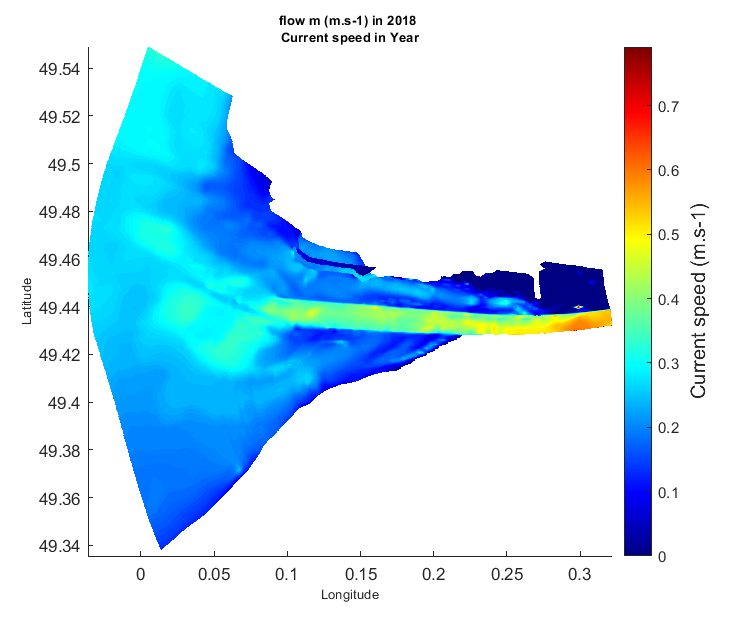

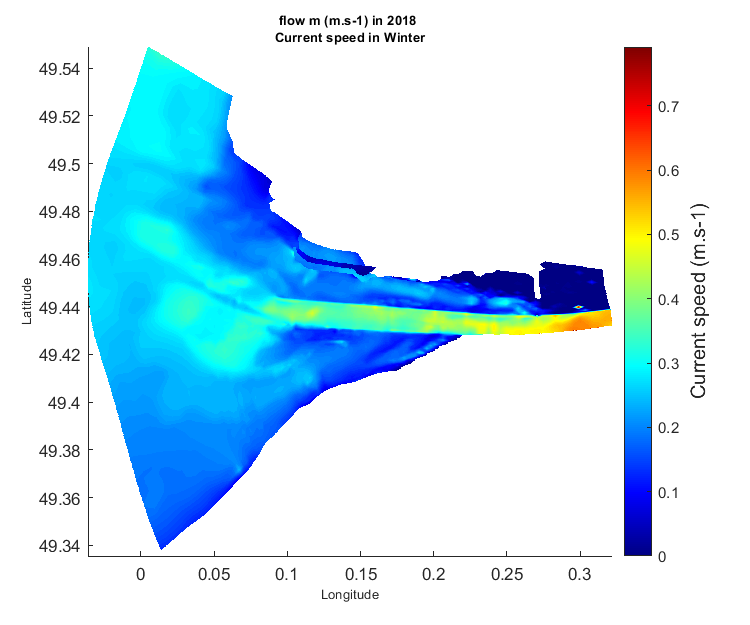

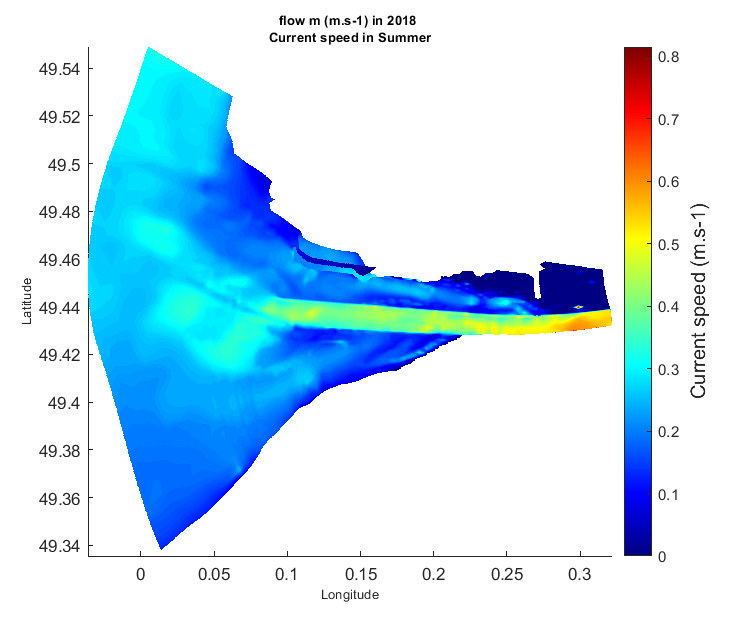

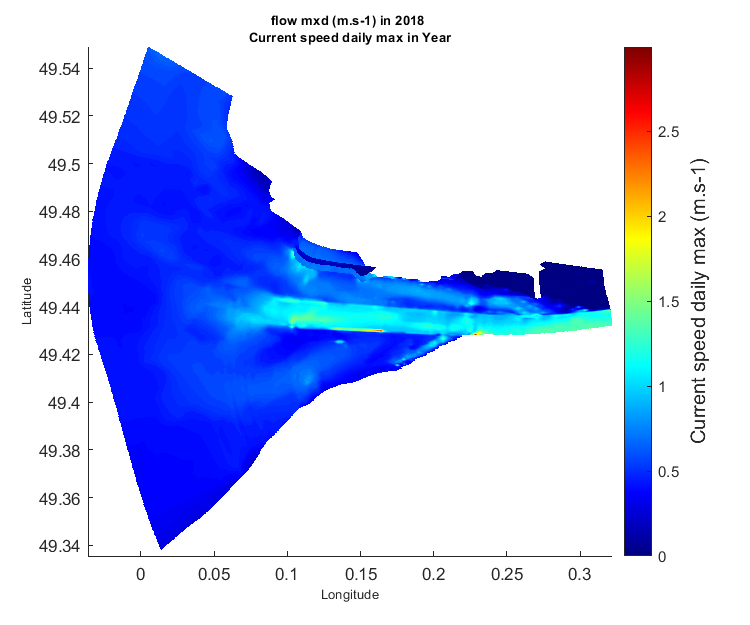

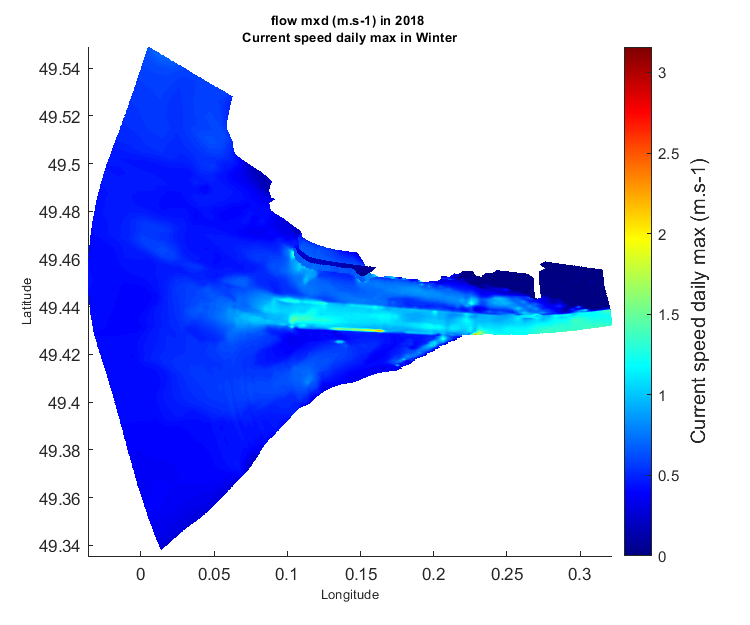

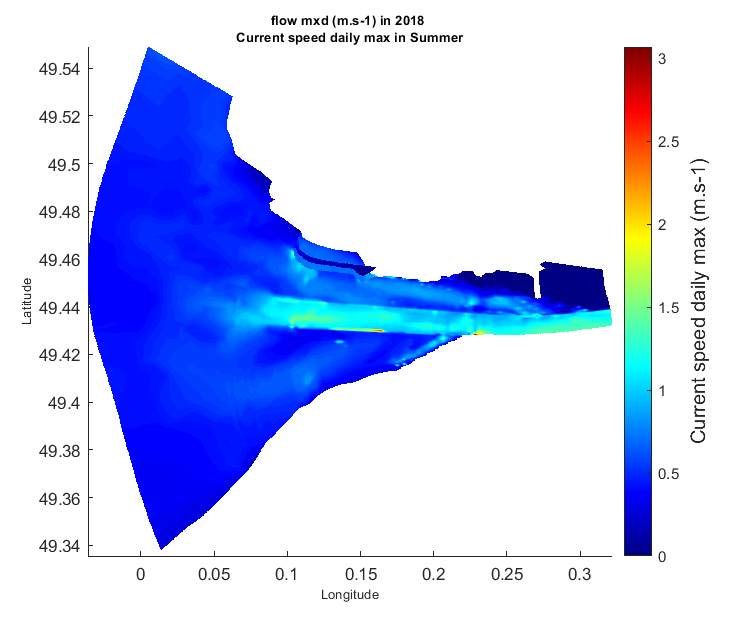

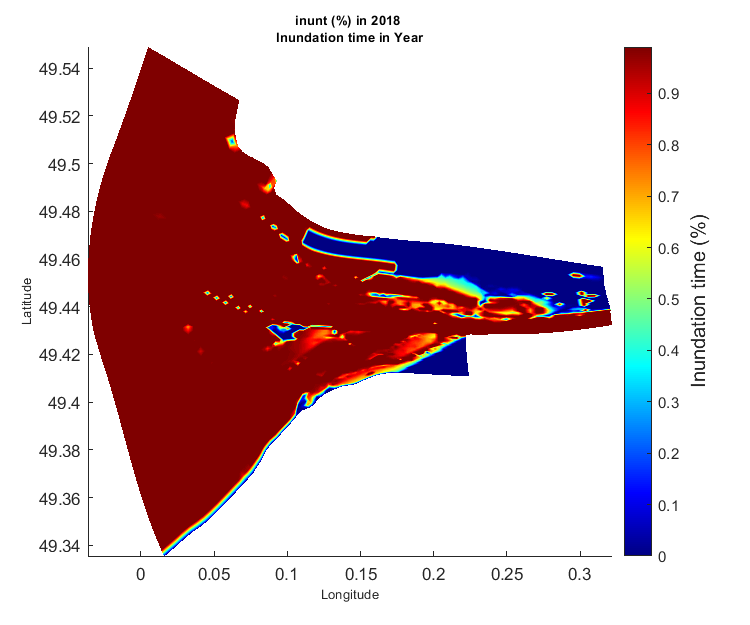

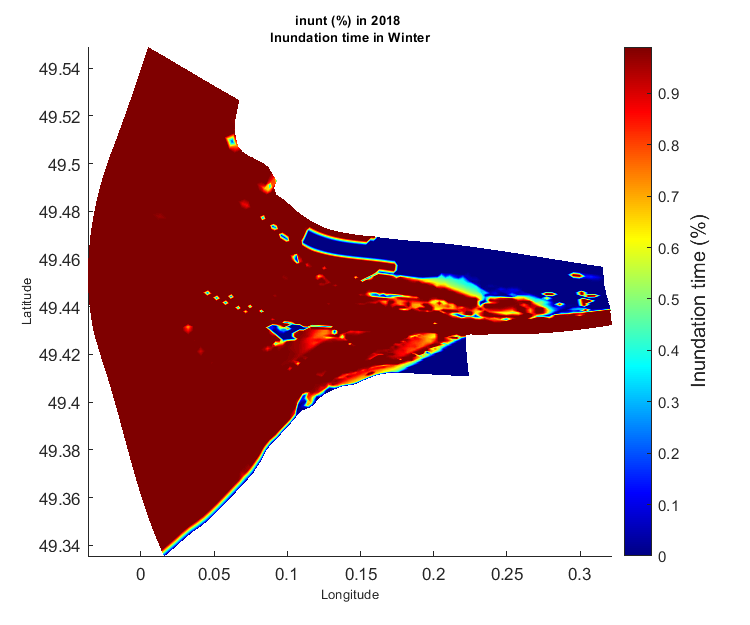

if edit == 3 || edit == 13 || edit == 23 || edit == 123
    for pre = pred
        for sa = sai
        % Recherche gamme maximale sur la periode pour echelle commune
        varmax = strcat("max(nc2d.",predict{pre,1},saison{sa,1},'_',string(an),",[],'all')"); maxx = 0;
        varmin = strcat("min(nc2d.",predict{pre,1},saison{sa,1},'_',string(an),",[],'all')"); minn = 0;
        for i = 1:length(varmax)
          try maxx = max(maxx,eval(varmax(i))); end
          try minn = min(minn,eval(varmin(i))); end
        end
        rgvar = [minn maxx];
%         axis tight manual % this ensures that getframe() returns a consistent size
        filename = [wdgraph,etude,'_Map_Anim_',predict{pre,1},'_',saison{sa,2},'.gif'];
        fig = figure;clf;hold on 
        set(gcf, 'Position', propimg);
          for ann = per
          hold on
            anstr = num2str(an(ann));
            vartitle = sprintf('%s (%s) in %s \n%s in %s', strrep(predict{pre,1},'_',' '), predict{pre,3}, anstr, predict{pre,2},saison{sa,2});
            x = eval(['nc2d.lon_nc_' anstr ';']);
            y = eval(['nc2d.lat_nc_' anstr ';']);
            z = eval(['nc2d.' predict{pre,1} saison{sa,1} '_' anstr ';']); 
            contourf(x,y,z,finesse, 'LineColor','flat') % ,'--','LineWidth',.1 ,'ShowText','on'
%             plot(dm_bdd(dm_bdd.Annee == anstr,:).longitude,dm_bdd(dm_bdd.Annee == anstr,:).latitude,'ko','markersize', 6)
            colormap(palette); c = colorbar; c.Label.String = sprintf('%s (%s)', strrep(predict{pre,2},'_',' '), predict{pre,3}); c.Label.FontSize = 12;
            xlabel('Longitude','FontSize',8); ylabel('Latitude','FontSize',8);
            title(vartitle,'FontSize',8,'FontWeight','bold');
            saveas(gcf,[wdgraph,'Unitaire/',etude,'_Map_',predict{pre,1},'_',saison{sa,2},'_',anstr,'.png']);
            if editgif == 1
                % Capture the plot as an image 
                frame = getframe(fig); 
                im = frame2im(frame); 
                [imind,cm] = rgb2ind(im,256); 
                % Write to the GIF File 
                if ann == 1 
                    imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
                else 
                    imwrite(imind,cm,filename,'gif','WriteMode','append'); 
                end
            end
          hold off
          end
        end
    end
end

### Creation de gif de chaque variable dans le temps

% h = figure;
% axis tight manual % this ensures that getframe() returns a consistent size
% filename = 'testAnimated.gif';
% for n = 1:0.5:5
%     % Draw plot for y = x.^n
%     x = 0:0.01:1;
%     y = x.^n;
%     plot(x,y) 
%     drawnow 
%       % Capture the plot as an image 
%       frame = getframe(h); 
%       im = frame2im(frame); 
%       [imind,cm] = rgb2ind(im,256); 
%       % Write to the GIF File 
%       if n == 1 
%           imwrite(imind,cm,filename,'gif', 'Loopcount',inf); 
%       else 
%           imwrite(imind,cm,filename,'gif','WriteMode','append'); 
%       end 
%   end
% You can use gif2avi() from the file exchange to convert from GIF to AVI or MP4 format.end % fin boucle sur type data

% end % Couche
toc

Elapsed time is 18424.187827 seconds.


load gong.mat; sound(y);% beep